# Projekt zaliczeniowy MATLAB

# Autor: Jakub Pączek Nr.Albumu: 414592

Dane których będę używał do projektu pochodzą ze strony [https://www.kaggle.com/datasets/shrirangmhalgi/engineering-colleges-in-india.](https://www.kaggle.com/datasets/shrirangmhalgi/engineering-colleges-in-india.) Zabrane w nich są statystyki dotyczące uczelni technicznych w Indiach. Dane są zebrane w tabeli, są to zarówno dane tekstowe, kategoryczne, liczbowe jak i data.

## Import danych

Importuje dane z pliku o nazwie engineering colleges in India.csv. Jest to arkusz kalkulacyjny. Podstawiam do zmiennej fname nazwę pliku. Wyznaczam następnie opcje importu i z ich użyciem czytam tabelę z pliku i zapisuje są do tabeli data. 

Przy wykonaniu kodu Matlab ostrzega o zamiane nazw kolumn. Dzieje się tak dlatego, że oryginalny plik w nazwach kolumn zawiera spacje.

fname = "engineering colleges in India.csv";
opts = detectImportOptions(fname);
data = readtable(fname, opts);

## Właściwy typ danych

Najpierw zależy mi żeby dane miały odpowiedni typ. Dane tekstowe mają typ 'cell', zazmieniam je więc na string, czyli napis lub categorical, typ kategoryczny. Dane liczbowe mają odpowiedni typ. Kolumna CampusSize zawiera liczbę, ale po nich jest jeszcze słowo 'Acres', należy to więc odpowiednio przekonwertować. Usuwam też zbędne kolumny, zawierają one długie opisy, zbędne do analizy danych.

display(data); %wyświetlam tabelę, by zobaczyć dane

data = 5446×15 table
                              CollegeName                              GendersAccepted      CampusSize      TotalStudentEnrollments    TotalFaculty    EstablishedYear    Rating                        University                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         

data.GendersAccepted = categorical(data.GendersAccepted, {'Co-Ed', 'Female', 'Male'}); %zamiana na typ kategoryczny
data.GendersAccepted = mergecats(data.GendersAccepted, {'Female', 'Male'}, 'Non-Co-Ed'); %łączenie kategorii
data.CampusSize = string(data.CampusSize); %zamiana na napis
data.CampusSize = replace(data.CampusSize, "Acres", "");
data.CampusSize = double(data.CampusSize);
data = removevars(data, ["University", "Courses", "Facilities"]); %usuwam zbędne kolumny
data.City = string(data.City);
data.State = string(data.State);
data.Country = string(data.Country);
data.CollegeType = categorical(data.CollegeType, {'Public/Government', 'Private'});

## Braki w danych

Uzupełniam braki z danych. Dla danych liczbowych używam metody "linear", czyli średniej sąsiednich elementów, dla danych kategorycznych używam metod "nearest" i "previous". 

W kolumnie Rating, zawierające punkty w rankingu, jedynie mała część obserwacji ma przypisaną wartość. Najlepiej więc to tak zostawić i odwoływać się potem tylko do tych wierszy, gdzie jest wartość.

display(sum(ismissing(data))); %wyświetlam ile jest obserwacji brakująych przed

           0          25        2772        1009         167         107        5119           0           0           0           7           6



data.GendersAccepted = fillmissing(data.GendersAccepted, "previous");
data.CampusSize = fillmissing(data.CampusSize, "linear");
data.TotalStudentEnrollments = fillmissing(data.TotalStudentEnrollments, "linear");
data.TotalFaculty = fillmissing(data.TotalFaculty, "linear");
data.EstablishedYear = fillmissing(data.EstablishedYear, "previous");
data.CollegeType = fillmissing(data.CollegeType, "nearest");
data.AverageFees = fillmissing(data.AverageFees, "linear");
display(sum(ismissing(data))); %wyświetlam ile jest obserwacji brakujących po

           0           0           0           0           0           0        5119           0           0           0           0           0



## Wartości odstające

Podmieniam teraz wartości odstające w danych. Robię to kilka razy w pętli z uwagi na ich dużą liczbę.

display(sum(isoutlier(data(:,vartype("numeric"))))); %wyświetlam ile jest wartości odstających przed

   714   537   281   872    29   187



for i = 1:4
    data.CampusSize = filloutliers(data.CampusSize, "nearest");
    data.TotalStudentEnrollments = filloutliers(data.TotalStudentEnrollments, "linear");
    data.TotalFaculty = filloutliers(data.TotalFaculty, "nearest");
    data.EstablishedYear = filloutliers(data.EstablishedYear, "previous");
    data.Rating = filloutliers(data.Rating, "nearest");
    data.AverageFees = filloutliers(data.AverageFees, "center");
end
display(sum(isoutlier(data(:,vartype("numeric"))))); %wyświetlam ile jest po

     0     0     0     0     0     0



## Timetable

W danych mam kolumnę zawierającą rok założenie uczelni. Na jej podstawie tworzę datę. Dla uproszczenia przyjmuje wszędzie dzień 1 stycznia. Następnie przenoszę nową kolumnę na początek tabeli i tworzę timetable.

data.EstablishedDate = datetime(data.EstablishedYear, 1, 1); %dodaje nową kolumnę
data = movevars(data, "EstablishedDate", Before="CollegeName");
datat = table2timetable(data);
datat.Properties.DimensionNames(1) = "Date"; %data jest teraz wymiarem tabeli
fprintf("Dolna granica daty wynosi: %s", bounds(datat.Date)); %wyświetlam dolną granicę daty

Dolna granica daty wynosi: 01-Jan-1995

datat1 = retime(datat, 'yearly'); %w tabeli datat1 data jest rozłożona regularnie co roku

## Wykresy

Pierwszy wykres to wykres pudełkowy rozmiaru kampusów.

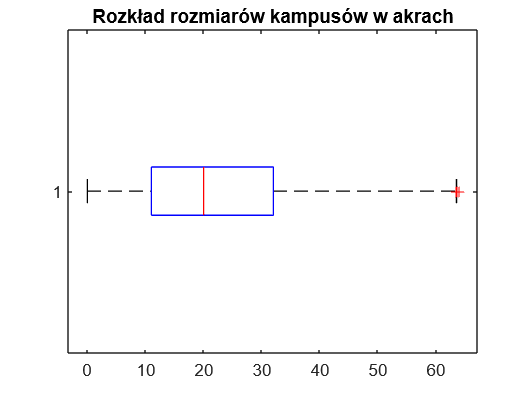

boxplot(data.CampusSize, 'Orientation', 'horizontal');
title('Rozkład rozmiarów kampusów w akrach');

Wykresy kołowe obrazujące charakter uczelni.

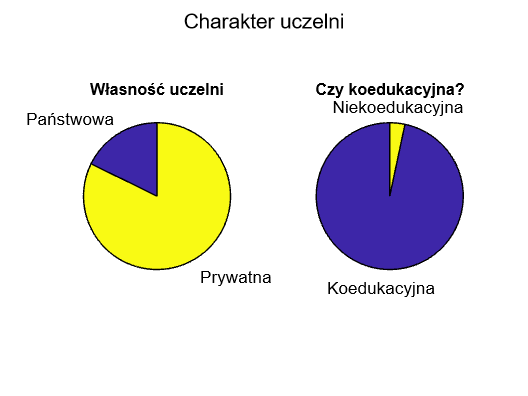

subplot(1, 2, 1);
s1 = pie(data.CollegeType, {}, {'Państwowa', 'Prywatna'});
t1 = title('Własność uczelni');
t1.Position = t1.Position + [0 0.1 0]; %umieszczam tytuły nieco wyżej
subplot(1, 2, 2);
s2 = pie(data.GendersAccepted, {}, {'Koedukacyjna', 'Niekoedukacyjna'});
t2 = title('Czy koedukacyjna?');
t2.Position = t2.Position + [0 0.1 0];
sgtitle('Charakter uczelni');

Histogram przedstawiający jak rozkłada się średnia opłata za studia na danej uczelni.

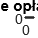

figure;
h = histogram(data.AverageFees);
title('Przeciętne opłaty za studia')
gc1 = gca;
gc1.XTickLabel = {'0', '100', '200', '300', '400', '500'};
gc1.XLabel.String = 'tyś. INR';

Wykres przedstawiający ile punktów w rankingach otrzymują uczelnie w kolejności od najlepszych do najgorszych. (Tylko uczelnie uwzględnione w rankingach)

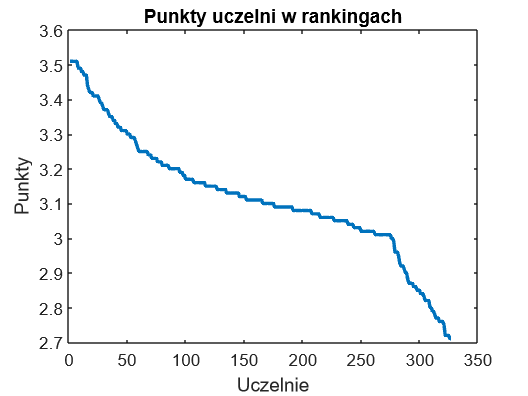

x = sort(data.Rating(~isnan(data.Rating)), 'descend');
p = plot(x);
title('Punkty uczelni w rankingach');
p.LineWidth = 2; %pogrubiam linię
gc2 = gca;
gc2.XLabel.String = 'Uczelnie';
gc2.YLabel.String = 'Punkty';

Dodaję najpierw do tabeli nową kolumnę 'Ratio' która zawiera stosunek całkowitej liczby pracowników naukowych 'TotalFaculty' do liczby studentów 'TotalStudentEnrollments'. Za pomocą wykresu bąbelkowego prezentuje rozkład tej zmiennej dla poszczególnych regionów Indii i typów uczelni.

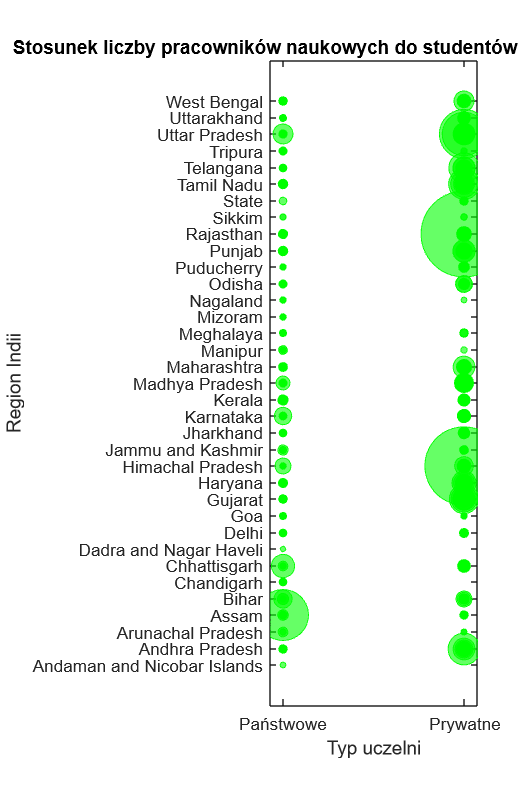

data.State = categorical(data.State); %muszę zamienić wartości w tabeli z napisów na dane kategoryczne
data.Ratio = data.TotalFaculty./data.TotalStudentEnrollments;
figure;
bubblechart(data.CollegeType, data.State, data.Ratio, "green");
gc3 = gcf;
gc3.Position(4) = gc3.Position(4)*2; %rozszerzam wykres
gc4 = gca;
gc4.XLabel.String = 'Typ uczelni';
gc4.YLabel.String = 'Region Indii';
gc4.XTickLabel = {'Państwowe', 'Prywatne'};
t3 = title('Stosunek liczby pracowników naukowych do studentów');
t3.Position = t3.Position+[-0.6 0 0]; %przesuwam tytuł w lewo

## Normalizacja

Tworzę nową macierz datax, gdzie znajdą się znormalizowane dane. Usuwam dane tekstowe i Rating, gdzie większość obserwacji jest brakująca, GendersAccepted i CollegeType mają po dwie kategorie, więc zamieniam je na zmienne binarne. Normalizuję resztę danych.

Przymuje AverageFees za wartość jaką chce obliczyć na podstawie modelu.

datax = removevars(data, ["CollegeName","Rating", "City", "State", "Country", "EstablishedDate", "Ratio", "AverageFees"]);
datax.GendersAccepted = double(datax.GendersAccepted);
datax.CollegeType = double(datax.CollegeType);
datax.GendersAccepted(data.GendersAccepted == 'Co-Ed') = 0;
datax.GendersAccepted(data.GendersAccepted == 'Non-Co-Ed') = 1;
datax.CollegeType(data.CollegeType == 'Public/Government') = 1;
datax.CollegeType(data.CollegeType == 'Private') = 0;
datax(:,2:5) = normalize(datax(:,2:5));
datax = table2array(datax);
Y = normalize(data.AverageFees); %to będzie wartość którą obliczę na podstawie modelu

## Zapis do pliku

save('Jakub_Paczek.mat', 'datax');

## Prognoza

n = height(datax); %wyznaczam liczbę obserwacji
partition = cvpartition(n, 'Holdout', 0.1); %podział na próbę testową i uczącą
idxTrain = training(partition); %indeksy dla części treningowej
dataxTrain = datax(idxTrain, :);
YTrain = Y(idxTrain); 
idxTest = test(partition); %indeksy dla części testowej
dataxTest = datax(idxTest, :);
YTest = Y(idxTest);
[coeff,score,latent,tsquared,explained,mu] = pca(dataxTrain); %analiza głownych składowych dla danych treningowych
fprintf("Procent zmienności dla 3 składowych: %f\n", sum(explained(1:3)));

Procent zmienności dla 3 składowych: 82.798878


fprintf("Procent zmienności dla 4 składowych: %f\n", sum(explained(1:4)));

Procent zmienności dla 4 składowych: 96.140077


Widzimy że conajmniej 95% zmienności wyjaśniają 4 pierwsze składowe.

idx =4;
mdl = fitctree(dataxTrain(:,1:idx), YTrain); %trenowanie modelu
scoreTest =(dataxTest-mu)*coeff(:,1:idx); %przekształcania zestawu danych testowych
YPredicted = predict(mdl, scoreTest(:,1:idx)); %dokonuje prognozy
errors = YTest - YPredicted; %wyznaczam błędy prognozy
fprintf("Średni błąd = %f\nMax błąd = %f\n", mean(abs(errors)), max(abs(errors)));

Średni błąd = 1.026407
Max błąd = 4.347682


## Inne metody grupowania i klasyfikacji

Tutaj tworzę model na podstawie innej metody grupowania i klasyfikacji.

idx = kmeans(datax, 2); % metoda grupowania k średnich
dataxTrain = datax(idx == 1);
YTrain = Y(idx == 1); 
YTest = Y(idx == 2);
dataxTest = datax(idx == 2); 
mdl = fitcknn(dataxTrain, YTrain); %klasyfikator k najbliższych sąsiadów
YPredicted = predict(mdl, dataxTest);
errors = YTest - YPredicted;
fprintf("\nŚredni błąd = %f\nMax błąd = %f", mean(abs(errors)), max(abs(errors)));


Średni błąd = 2.085179
Max błąd = 3.576250

Tu zastosuję inną metodę grupowania, metodę klastrowania i zwizualizuję wynik jej działania.

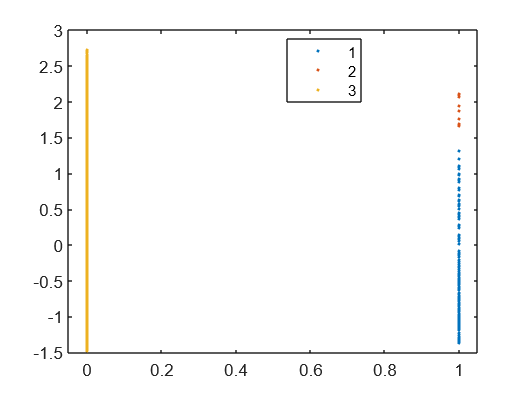

c = clusterdata(datax(:,[1,3]), 3);
figure; %metoda klastrowania na podstawie odległości
gscatter(datax(:,1), datax(:,3), c);